# Signal Generation and Visualization

## Periodic Waveforms

fs = 10000;
t = 0:1/fs:1.5;

### Sawtooth

x1 = sawtooth(2*pi*50*t);
plot(t,x1)
axis([0 0.2 -1.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Sawtooth Periodic Wave')
pspectrum(x1,fs,'Leakage',0.91)

### Square

x2 = square(2*pi*50*t);
plot(t,x2)
axis([0 0.2 -1.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Square Periodic Wave')
pspectrum(x2,fs,'Leakage',0.91)

## Aperiodic Waveforms

fs = 10000;
t = -1:1/fs:1;
figure

### Tripuls

x1 = tripuls(t,20e-3);
plot(t,x1)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Trangular Aperiodic Pulse')

### Rectpuls

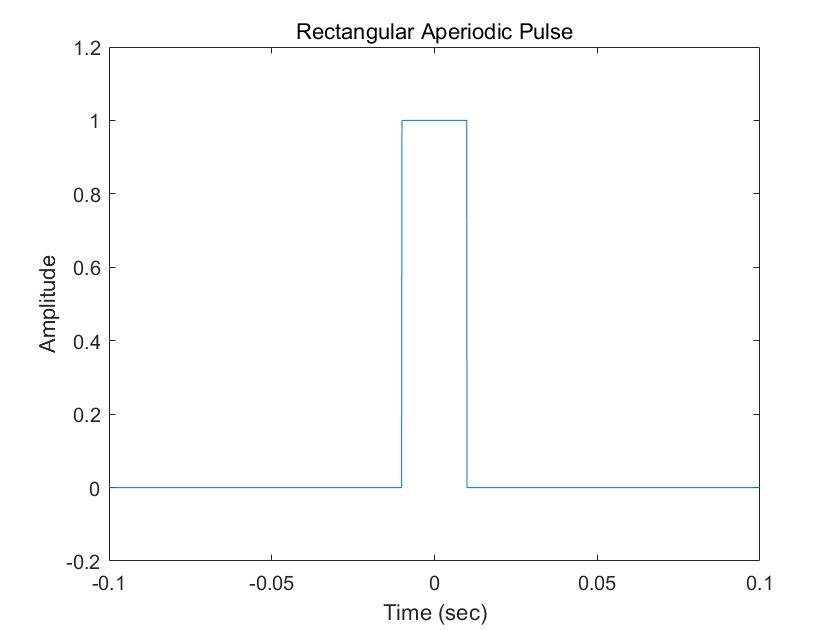

x2 = rectpuls(t,20e-3);
plot(t,x2)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Rectangular Aperiodic Pulse')

### Gauspuls

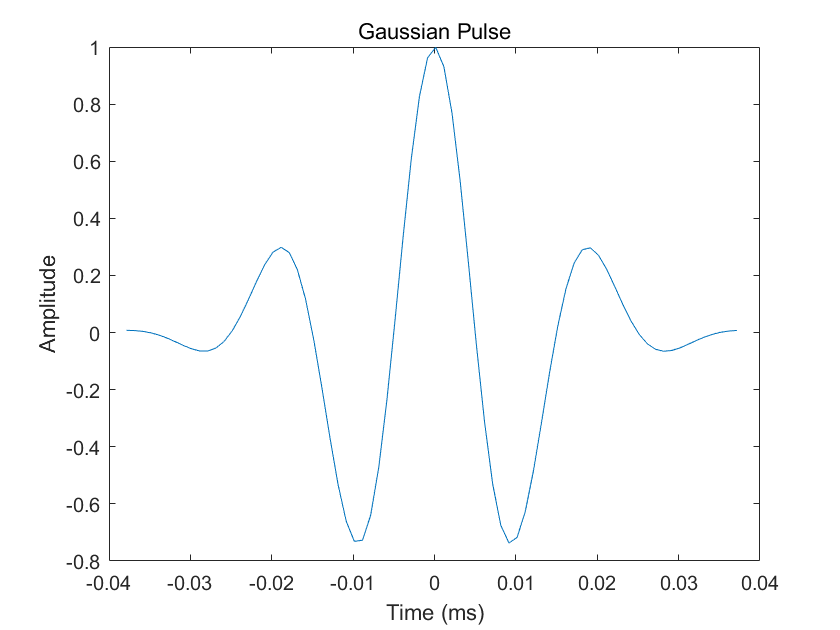

tc = gauspuls('cutoff',50e3,0.6,[],-40);
t1 = -tc:1e-6:tc;
y1 = gauspuls(t1, 50e3, 0.6);
plot(t1*1e3, y1)
xlabel('Time (ms)')
ylabel('Amplitude')
title('Gaussian Pulse')

### sinc

t2 = linspace(-5,5)

t2 =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


y2 = sinc(t2)

y2 =     0.0000    0.0203    0.0393    0.0552    0.0661    0.0708    0.0685    0.0590    0.0431    0.0219   -0.0025   -0.0280   -0.0519   -0.0719   -0.0856   -0.0912   -0.0879   -0.0753   -0.0541   -0.0259    0.0068    0.0411    0.0737    0.1010    0.1201    0.1282    0.1237    0.1058    0.0753    0.0339   -0.0154   -0.0683   -0.1201   -0.1654   -0.1990   -0.2160   -0.2123   -0.1852   -0.1332   -0.0568    0.0420    0.1593    0.2899    0.4273    0.5643    0.6932    0.8067    0.8984    0.9627    0.9958


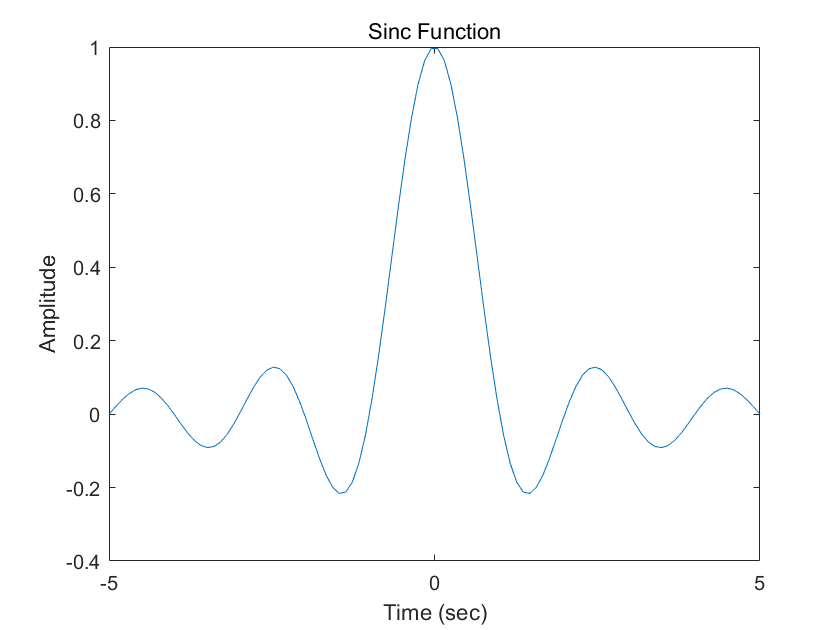

plot(t2, y2)
xlabel('Time (sec)')
ylabel('Amplitude')
title('Sinc Function')

## Swept-Frequency Waveforms

### linear chirp

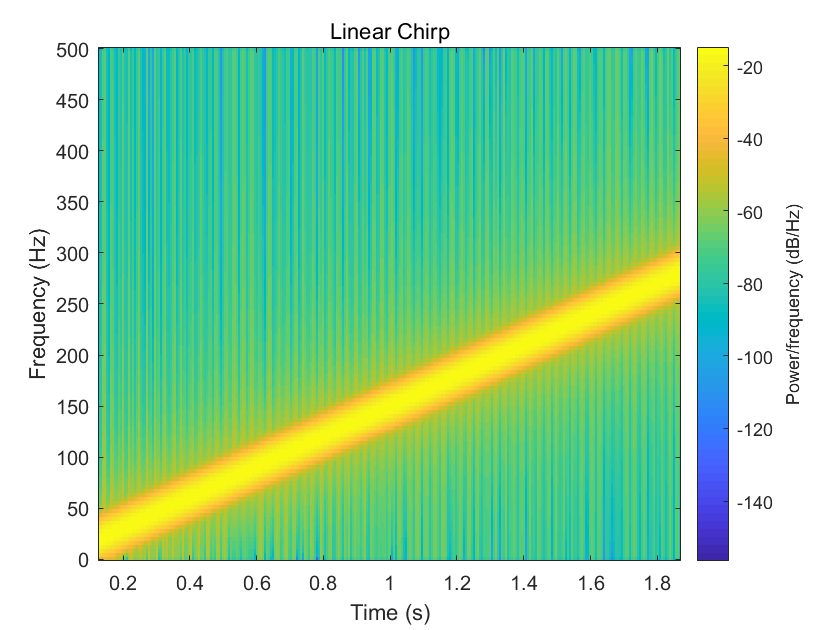

t = 0:0.001:2;
ylin = chirp(t, 0, 1, 150);
spectrogram(ylin,  256, 250, 256, 1e3, 'yaxis')
title('Linear Chirp')

### Quadratic Chirp

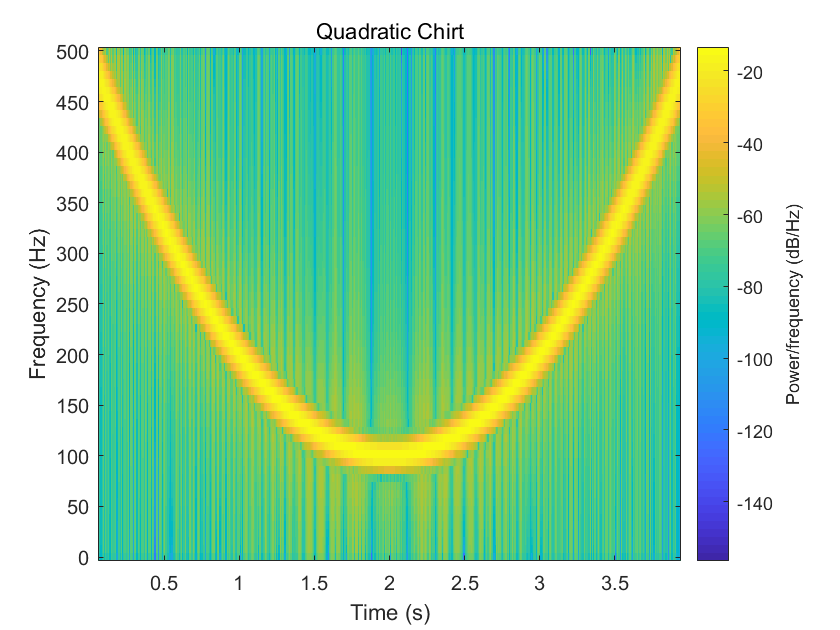

t = -2:0.001:2;
yq = chirp(t, 100, 1, 200, 'quadratic');
spectrogram(yq, 128, 120, 128, 1e3, 'yaxis')
title('Quadratic Chirt')

### Convex Quadratic chirp

t = -1:0.001:1;
ycx = chirp(t, 100, 1, 400, 'q', [], 'convex');

ycx =     1.0000    0.8079    0.3018   -0.3251   -0.8264   -0.9989   -0.7674   -0.2202    0.4209    0.8888    0.9824    0.6558    0.0438   -0.5902   -0.9662   -0.9123   -0.4462    0.2255    0.7963    0.9989    0.7324    0.1168   -0.5576   -0.9645   -0.9010   -0.3917    0.3152    0.8662    0.9786    0.5885   -0.1085   -0.7514   -0.9997   -0.7155   -0.0448    0.6528    0.9950    0.7877    0.1396   -0.5897   -0.9863   -0.8185   -0.1763    0.5711    0.9849    0.8149    0.1560   -0.5995   -0.9922   -0.7763


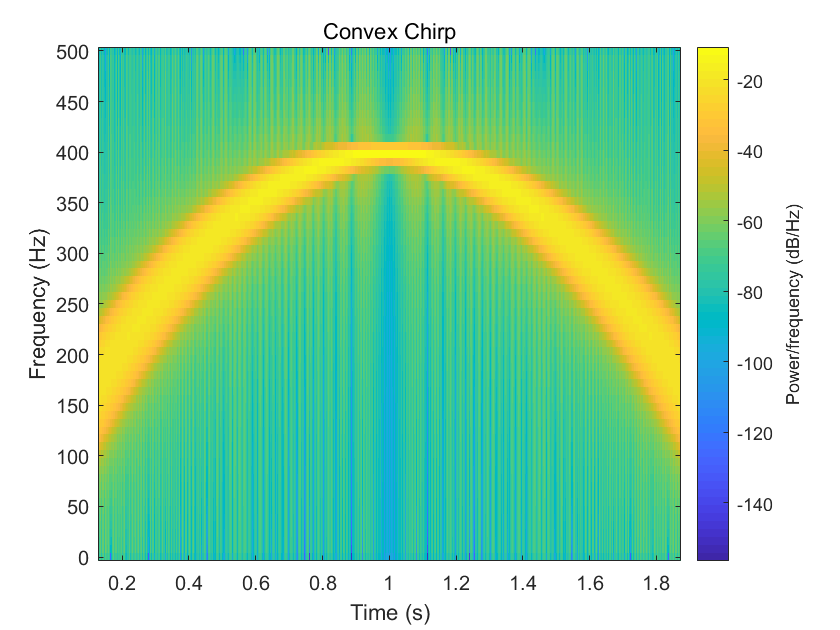

spectrogram(ycx, 256, 255, 128, 1000, 'yaxis')
title('Convex Chirp')

### Voltage-Controlled Oscillator

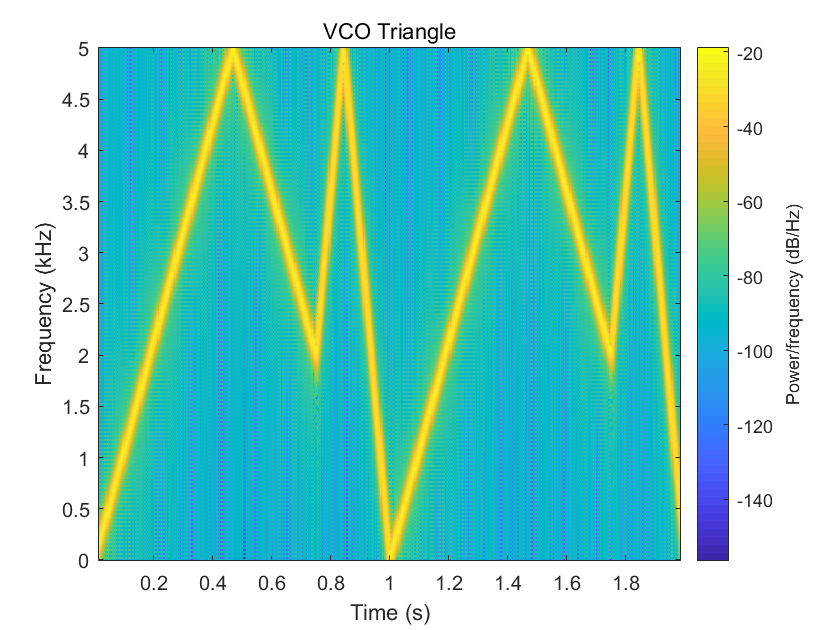

fs = 10000;
t = 0:1/fs:2;
x = vco(sawtooth(2*pi*t,0.75),0.4*fs,fs);
spectrogram(x, kaiser(256,5),220,512,fs,'yaxis')
title('VCO Triangle')

## Pulse Trains

### Rectangular pulses

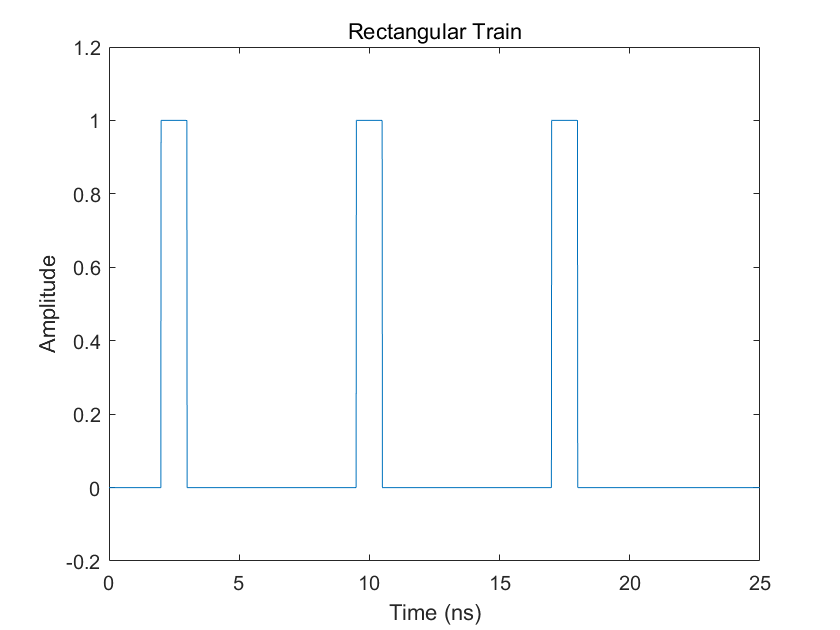

fs = 100e9;
D = [2.5 10 17.5]' * 1e-9;
t = 0:1/fs:2500/fs;
w = 1e-9;
yp = pulstran(t, D, @rectpuls, w);
plot(t*1e9, yp);
axis([0 25 -0.2 1.2])
xlabel('Time (ns)')
ylabel('Amplitude')
title('Rectangular Train')

### Gaussian pulses

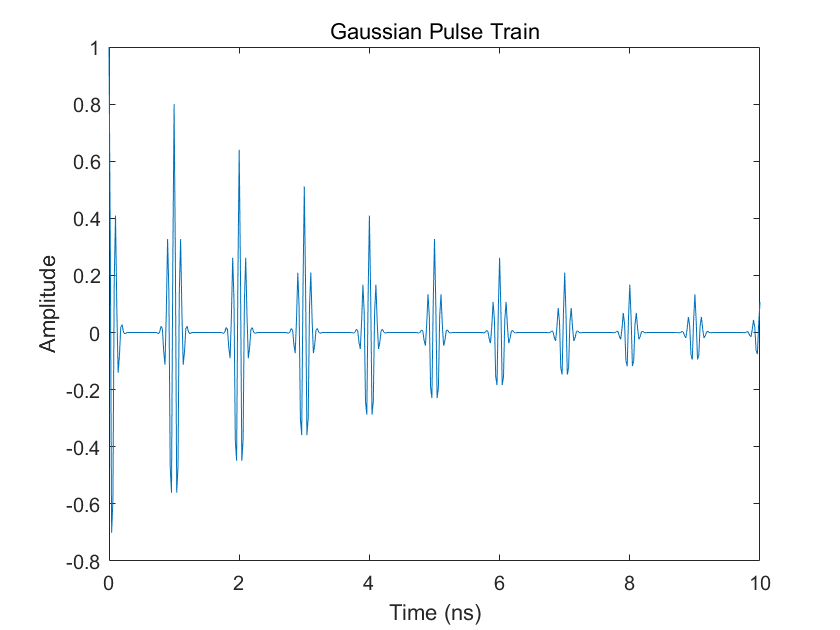

fs = 50e3;
t = 0:1/fs:10e-3;
D = [0:1/1e3 :10e-3;0.8.^(0:10)]';
Y = pulstran(t, D, @gauspuls,10e3, .5);
plot(t*1e3, Y);
xlabel('Time (ns)')
ylabel('Amplitude')
title('Gaussian Pulse Train')